**3.1 Edge Detection**

a) Download `macritchie.jpg’ from edveNTUre and convert the image to grayscale. Display the image.

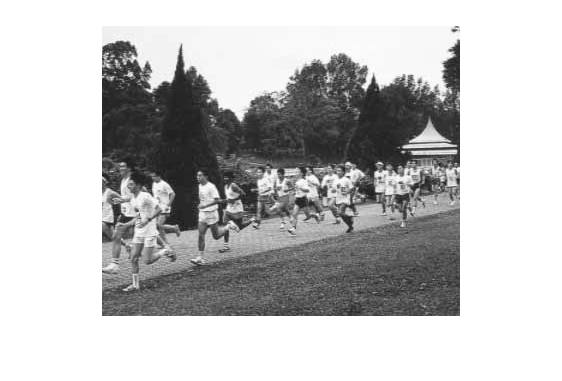

image = imread('images/macritchie.jpg');
% imshow(image);
image = rgb2gray(image);
imshow(image);

b) Create 3x3 horizontal and vertical Sobel masks and filter the image using conv2. Display the edge-filtered images. What happens to edges which are not strictly vertical nor horizontal, i.e. diagonal?

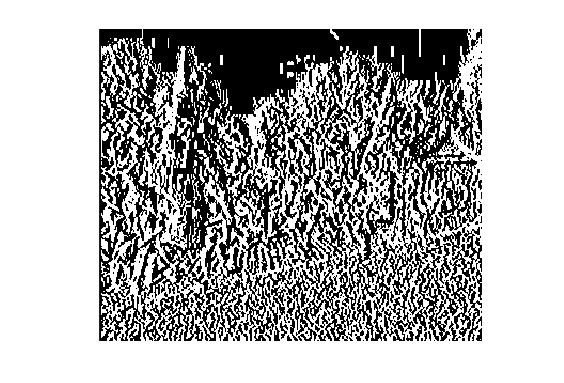

verticalSobelMask = [
    -1, -2, -1;
     0,  0,  0;
     1,  2,  1;
];

horizontalSobelMask = [
    -1,  0,  1;
    -2,  0,  2;
    -1,  0,  1;
];

verticalEdgeImage = conv2(image, verticalSobelMask);
imshow(filteredImage);


horizontalEdgeImage = conv2(image, horizontalSobelMask);
imshow(filteredImage);

diagonal edges: They are still detected, because a diagonal edge has changes in both horizontal and vertical direction. Changes in either direction would be detected by the relevant filter.

c) Generate a combined edge image by squaring (i.e. .^2) the horizontal and vertical edge images and adding the squared images. Suggest a reason why a squaring operation is carried out.

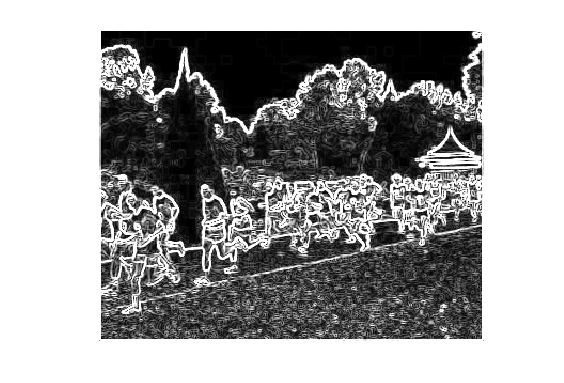

combinedEdgeImage = verticalEdgeImage.^2 + horizontalEdgeImage.^2;

% sqrt makes it better
combinedEdgeImage = combinedEdgeImage.^0.5;
displayImage = uint8(combinedEdgeImage);

% commented-out code results in similar-looking displayImage
% combinedEdgeImage = abs(verticalEdgeImage) + abs(horizontalEdgeImage);
% displayImage = uint8(combinedEdgeImage);

imshow(displayImage);

reason for squaring: If no squaring is done, a negative pixel value in the vertical edge image can get canceled out by a positive pixel value in the horizontal edge image, and vice versa. This means that edge information would be lost. By squaring the images, the values will all be positive, such that when added together, the edge information remains, as larger positive values.

In fact, adding the absolute edge maps together can achieve the same effect. I think one advantage squaring has over using absolute is that the difference between edge and non-edge is amplified, since squaring results in a large positive value for an edge but only a small positive value for non-edge.

d) Threshold the edge image E at value t by

>> Et = E>t;

This creates a binary image. Try different threshold values and display the binary edge images. What are the advantages and disadvantages of using different thresholds?

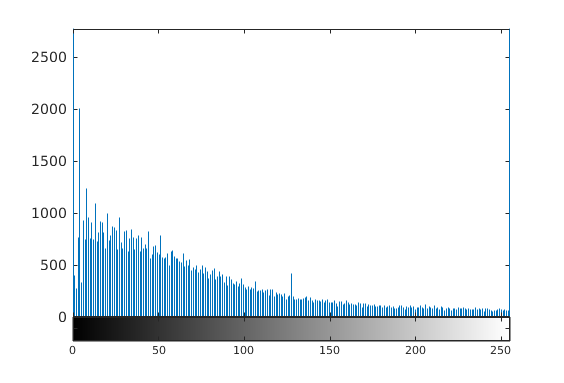

% see the histogram to better decide thresholds
imhist(displayImage, 255);

Threshold in the middle appears to be the best, since there seems to be a change in slope there. Going to try threshold at 25th and 75th percentile for comparison.

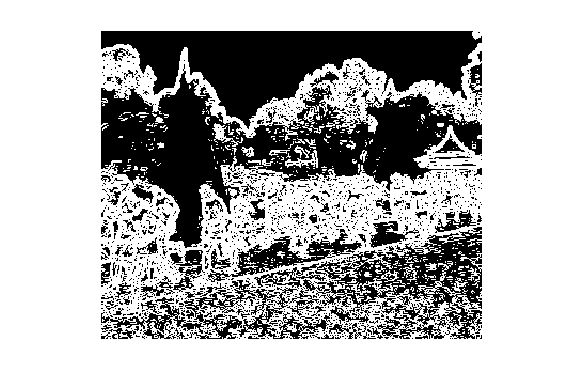

maxValue = max(displayImage(:));
minValue = min(displayImage(:));

difference = maxValue - minValue;

lowThreshold = 0.25 * difference;
midThreshold = 0.5 * difference;
highThreshold = 0.75 * difference;

binarisedImage = displayImage > lowThreshold;
imshow(binarisedImage);

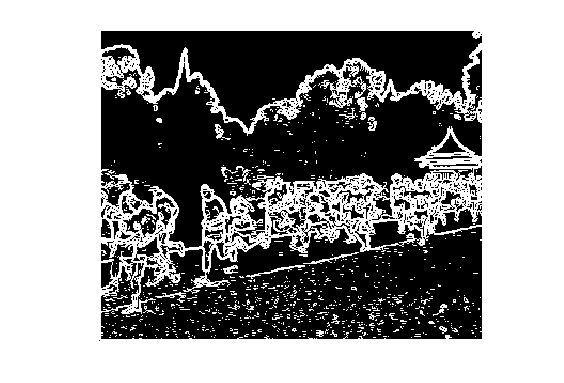


binarisedImage = displayImage > midThreshold;
imshow(binarisedImage);

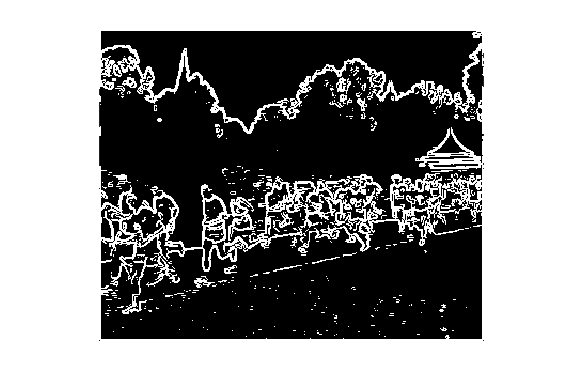


binarisedImage = displayImage > highThreshold;
imshow(binarisedImage);

advantages and disadvantages: Using a higher threshold results in less noise, but also result in less edge information kept.

e) Recompute the edge image using the more advanced Canny edge detection algorithm with tl=0.04, th=0.1, sigma=1.0

>> E = edge(I,’canny’,[tl th],sigma);

This generates a binary image without the need for thresholding.

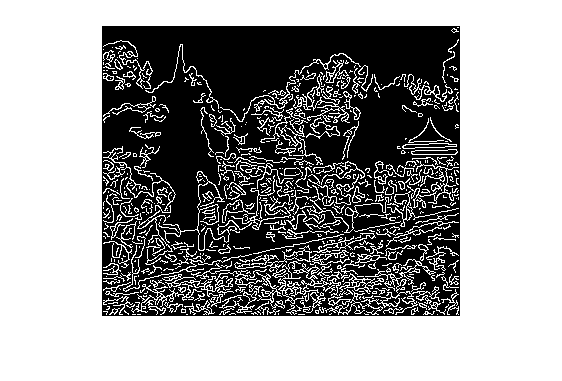

tl = 0.04;
th = 0.1;
sigma = 1.0;

binarisedImage = edge(image, 'Canny', [tl, th], sigma);
imshow(binarisedImage);

(i) Try different values of sigma ranging from 1.0 to 5.0 and determine the effect on the edge images. What do you see and can you give an explanation for why this occurs? Discuss how different sigma are suitable for (a) noisy edgel removal, and (b) location accuracy of edgels.

'part i'

ans = 'part i'

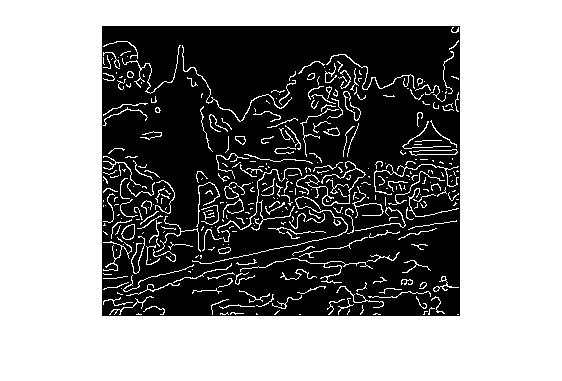

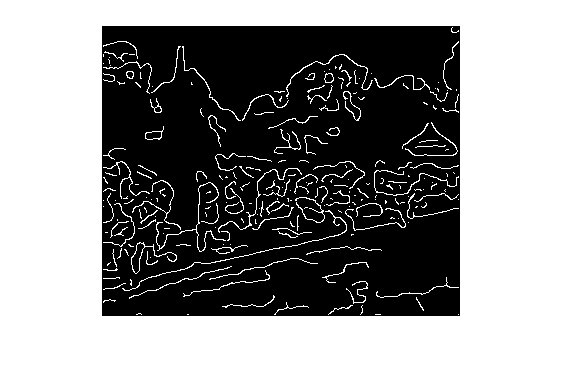

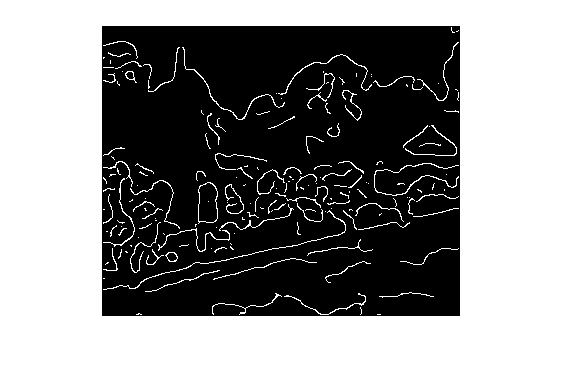

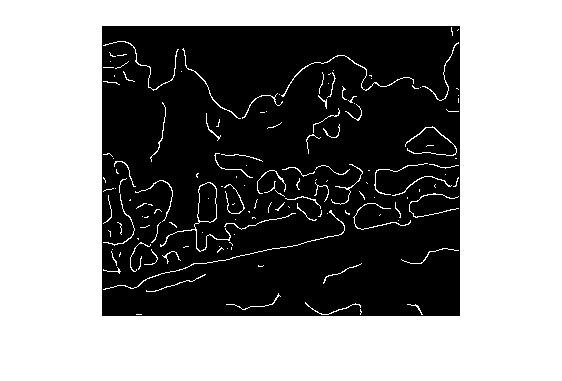

for sigma = 1:5
    binarisedImage = edge(image, 'Canny', [tl, th], sigma);
    figure();
    imshow(binarisedImage);
end

TODO

(ii) Try raising and lowering the value of tl. What does this do? How does this relate to your knowledge of the Canny algorithm?

'part ii'

ans = 'part ii'

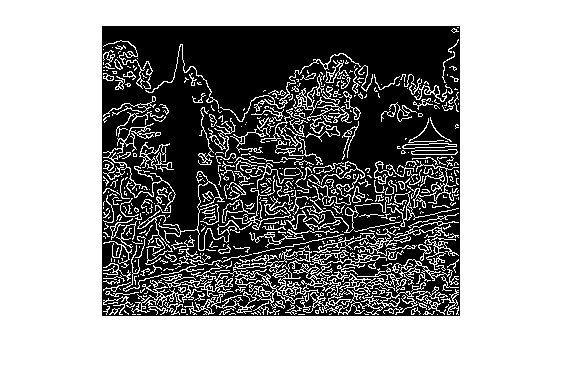

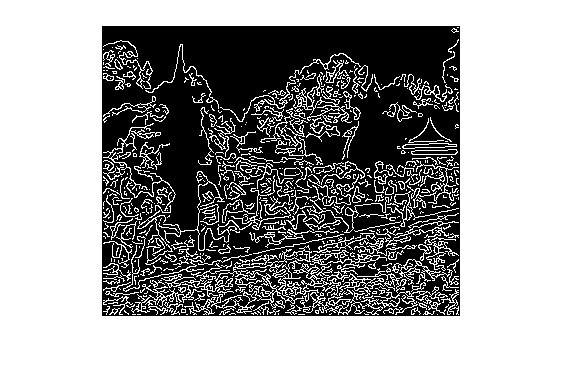

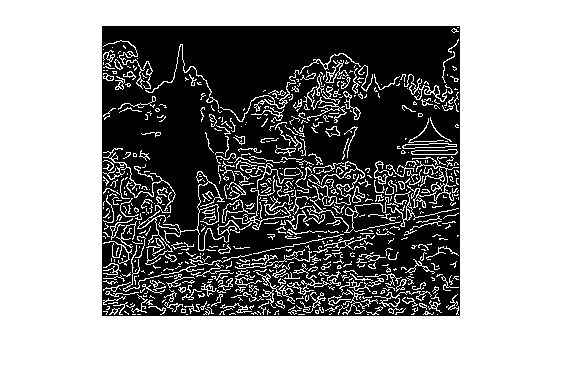

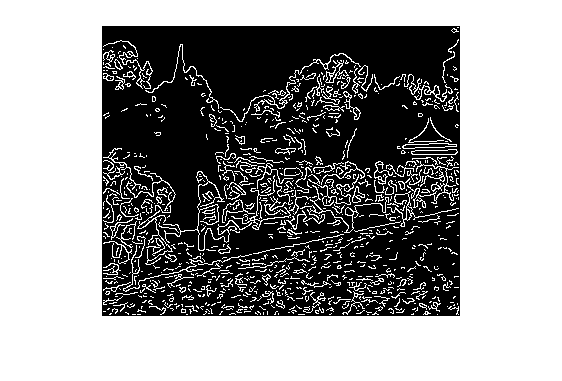

sigma = 1.0;
for index = 0:4
    tl = index * 0.02;
    binarisedImage = edge(image, 'Canny', [tl, th], sigma);
    figure();
    imshow(binarisedImage);
end

TODO